% %% HOW TO USE
% % 1. Right click on the main folder 'Generative Model Algorithm' (go back using the backward arrow) and click add
% % to path (folders and subfolders). Then open the folder.
% % 2. Put the number of required powertrains and required MAE over here.
% % 3. Run the script. 
% 
% % Inputs
library = library_gen('Powertrain_Library_GenAI');
params_file = 'parameters_database_one_conf-25%.mat'
load(params_file)
DriveCycle = importdata('WLTP_class3_V5.mat'); % Use a drive cycle. Use WLTP for now.
required_powertrains = 3; % Write here how many powertrain designs are needed.
required_MAE = 10; % MAE threshold to be considered an acceptable design (lower means more accurate design but much more time)

Genetic Algorithm inputs
initial_population = 2; % Initial population created before putting it into the genetic algorithm
iteration_population = 5; % Maximum number of population to be considered for mutation or to be a parent (Best ones after sorting)
max_iterations = 100; % Maximum number of iterations

create_offspring = true; % Does the algorithm create offspring?
n_offspring_per_iteration = 1; % Number of offspring created each iteration

mutate = true; % Does the algorithm create mutation?
n_mutations_per_iteration = 1; % Number of mutations created each iteration

create_new_powertrains = false; % Does the algorithm create new powertrain randomly?
n_new_powertrains_per_iteration = 1; % Number of new randonly generated powertrains each iteration

global max_repeat
max_repeat = 01; % This must match the variable with same name in modified_layout_gen_veh.m

global variation
% variation = 0.1; % This is used when one configuration parameter database is used to randomize the parameters in components. The value is a percentage of how much it changes (+/-)

% Initialize an array of structures
tic;
if exist('powertrains', 'var') == 1
    clear powertrains;
end
warning('on', 'verbose');

warning off Simulink:Engine:MdlFileShadowedByFile

% Calculate the number of created pieces per iteration
n_offspring_per_iteration = double(create_offspring) * n_offspring_per_iteration;
n_mutations_per_iteration = double(mutate) * n_mutations_per_iteration;
n_new_powertrains_per_iteration = double(create_new_powertrains) * n_new_powertrains_per_iteration;


powertrains(required_powertrains) = struct();
powertrains_iteration = struct();


% Initialization 
stored_powertrains = 0;
created_powertrains = 0;

while stored_powertrains ~= initial_population
    % Run the design algorithm 
    [results, layout] = GenDesignIteration(library, DriveCycle, parameters);
    
    % Update the number of created powertrains
    if ~isinf(results.MAE)
        created_powertrains = created_powertrains + 1
    end

    % Check if the MAE is less than required
    if results.MAE < required_MAE      
        [powertrains, stored_powertrains] = save_powertrain(powertrains, stored_powertrains, results, layout);    
    end

end

created_powertrains = 1

stored_powertrains = 1

created_powertrains = 2

created_powertrains = 3

created_powertrains = 4

created_powertrains = 5

stored_powertrains = 2

% Take max values of some results
results_values = [powertrains.results];
max_MAE = max([results_values.MAE]);
max_E_specific = max([results_values.E_specific]);
max_cost = max([results_values.cost]);
max_emissions = max([results_values.emissions]);

% Take length of powertrains struct
powertrains_length = sum(~cellfun(@isempty, {powertrains.layout}));
% Update powertrains fitnesses while normalizing
for i = 1:powertrains_length
    powertrains(i).layout.layout_fitness = fitness_function(powertrains(i).results, max_MAE, max_E_specific, max_cost, max_emissions);
end

iteration = 1

iteration = 1

created_with_crossover = 0;
created_with_mutation = 0;
while stored_powertrains < required_powertrains && iteration < max_iterations
    stored_powertrains_beginning = stored_powertrains;
    % This function is used to sort the powertrains struct to select best population for creating offspring and mutations
    powertrains_iteration = powertrains;
    if stored_powertrains > iteration_population
        % Step 1: Find indices of initialized elements (elements with non-empty layout)
        initialized_indices = find(arrayfun(@(x) isfield(x, 'layout') && isfield(x.layout, 'layout_fitness'), powertrains));
        
        % Step 2: Extract layout_fitness values only from initialized elements
        layout_fitness_values = arrayfun(@(x) x.layout.layout_fitness, powertrains(initialized_indices));
        
        % Step 3: Sort the layout_fitness values and get the sorted indices
        [~, sorted_relative_indices] = sort(layout_fitness_values);
        
        % Step 4: Map the relative sorted indices back to the original struct array
        sorted_indices = initialized_indices(sorted_relative_indices);
        
        % Step 5: Reorder the powertrains struct based on the sorted indices
        powertrains_sorted = powertrains(sorted_indices);
        
        % Step 6: Get the first 5 elements with the smallest layout_fitness values
        powertrains_iteration = powertrains_sorted(1:iteration_population);
    end
    for x = 1:n_offspring_per_iteration
        disp("Creating an offspring")
        % Select parents and the index that the parents will cross-over over
        % The left side of parent1 is selected and the right side of parent2
        [parent1, parent2, idx_to_cross_over] = select_parents_and_co_point(powertrains_iteration);
        if ~idx_to_cross_over
            break
        end
        % The returned idx_to_cross_over is returned as a list of 2 items
        idx_p1 = idx_to_cross_over(1);
        idx_p2 = idx_to_cross_over(2);

        % Making the offspring using the parents and the cross-over point
        offspring.layout = [parent1.layout(1:idx_p1), parent2.layout(idx_p2:end)];
        offspring.layout_conn_type = [parent1.layout_conn_type(1:idx_p1), parent2.layout_conn_type(idx_p2:end)];
        offspring.layout_conn_dir = [parent1.layout_conn_dir(1:idx_p1), parent2.layout_conn_dir(idx_p2:end)];
        offspring.params = [parent1.params(1:idx_p1), parent2.params(idx_p2:end)];
        offspring.layout_fitness = 0.0;
        
        % Doing mandatory checks, that created offspring is unique and does not break the repeating constraint
        doesnt_repeat = max_repeat_check(offspring.layout, max_repeat);
        
        % If true simulate the powertran and save if MAE is below acceptable amount
        if doesnt_repeat
            [results, layout] = GenDesignIteration(library, DriveCycle, parameters, offspring, true);
            if ~isinf(results.MAE)
                created_powertrains = created_powertrains + 1
            end
            if results.MAE < required_MAE      
               [powertrains, stored_powertrains] = save_powertrain(powertrains, stored_powertrains, results, layout);    
               created_with_crossover = created_with_crossover + 1;
            end
        end
        % Check if the required number of powertrains has been reached
        if stored_powertrains == required_powertrains
            disp('Required number of powertrains reached.');
            n_offspring_per_iteration = 0;
            n_mutations_per_iteration = 0;
            n_new_powertrains_per_iteration = 0;
            break
        end
    end
    
    % Check if the required number of powertrains has been reached
    if stored_powertrains == required_powertrains
        disp('Required number of powertrains reached.');
        n_offspring_per_iteration = 0;
        n_mutations_per_iteration = 0;
        n_new_powertrains_per_iteration = 0;
    end

    for x = 1:n_mutations_per_iteration
        disp("Creating a mutation")
        % Take the length of the powertrains list to select a powertrain randomly
        powertrains_length = sum(~cellfun(@isempty, {powertrains_iteration.layout}));
        selected_powertrain = powertrains_iteration(randi([1,powertrains_length], 1)).layout;
        
        % Take the length of a layout to determine a cutting point randomly
        
        layout_length = length(selected_powertrain.layout);
        cutting_point = randi([2, layout_length - 1]);

        % Delete the left side of the powertrain from the cutting point
        selected_powertrain.layout = selected_powertrain.layout(cutting_point:end);
        selected_powertrain.layout_conn_type = selected_powertrain.layout_conn_type(cutting_point:end);
        selected_powertrain.layout_conn_dir = selected_powertrain.layout_conn_dir(cutting_point:end);
        selected_powertrain.params = selected_powertrain.params(cutting_point:end);

        % Go back to the design algorithm to rebuild the cut powertrain
        [results, layout] = GenDesignIteration(library, DriveCycle, parameters, selected_powertrain);

        % Update created powertrains and save powertrain if MAE is acceptable
        if ~isinf(results.MAE)
            created_powertrains = created_powertrains + 1
        end
        if results.MAE < required_MAE   
            [powertrains, stored_powertrains] = save_powertrain(powertrains, stored_powertrains, results, layout);
            created_with_mutation = created_with_mutation + 1;
        end
        % Check if the required number of powertrains has been reached
        if stored_powertrains == required_powertrains
            disp('Required number of powertrains reached.');
            n_offspring_per_iteration = 0;
            n_mutations_per_iteration = 0;
            n_new_powertrains_per_iteration = 0;
            break
        end
    end

    for x = 1:n_new_powertrains_per_iteration 
        disp("Creating a new powertrain")
        % Run the design algorithm 
        [results, layout] = GenDesignIteration(library, DriveCycle, parameters);
            
        % Check if the MAE is less than required and if the layout is unique
        if ~isinf(results.MAE)
            created_powertrains = created_powertrains + 1
        end
        if results.MAE < required_MAE   
            [powertrains, stored_powertrains] = save_powertrain(powertrains,stored_powertrains, results, layout);    
        end
        % Check if the required number of powertrains has been reached
        if stored_powertrains == required_powertrains
            disp('Required number of powertrains reached.');
            n_offspring_per_iteration = 0;
            n_mutations_per_iteration = 0;
            n_new_powertrains_per_iteration = 0;
            break
        end
    end

    if stored_powertrains > stored_powertrains_beginning
        % Take max values of some results
        results_values = [powertrains.results];
        max_MAE = max([results_values.MAE]);
        max_E_specific = max([results_values.E_specific]);
        max_cost = max([results_values.cost]);
        max_emissions = max([results_values.emissions]);
        
        % Take length of powertrains struct
        powertrains_length = sum(~cellfun(@isempty, {powertrains.layout}));
        % Update powertrains fitnesses while normalizing
        for i = 1:powertrains_length
            powertrains(i).layout.layout_fitness = fitness_function(powertrains(i).results, max_MAE, max_E_specific, max_cost, max_emissions);
        end
    end
    iteration = iteration + 1
end

elapsed_time = 1.2931e+03

% % Get the current user's root directory (platform independent)
% user_root = userpath; % Gets the MATLAB default user folder
% 
% % Remove the trailing semicolon from userpath (MATLAB appends a semicolon)
% if user_root(end) == ';'
%     user_root(end) = [];
% end
% 
% % Define the relative folder path from the user's MATLAB directory
% save_directory = fullfile(user_root, 'Genetic Algorithm', 'Results', save_folder);
% 
% save(fullfile(save_directory, 'powertrains.mat'), 'powertrains');
 elapsed_time = toc
% bdclose('all');


% Display the layout and info of each stored powertrain
% emissions_data = zeros(1,required_powertrains);
% cost_data = zeros(1,required_powertrains);
% MAE_data = zeros(1,required_powertrains);
% E_specific_data = zeros(1, required_powertrains);
% fitness_data = zeros(1, required_powertrains);
% icev = zeros(1,required_powertrains);
% ev = zeros(1,required_powertrains);
% shev = zeros(1,required_powertrains);
% 
% 
% for i = 1:required_powertrains
%     disp(powertrains(i).results.layout);
%     if ismember('GEN', powertrains(i).results.layout)
%         shev(i) = 1;
%     elseif ismember('ICE', powertrains(i).results.layout)
%         icev(i) = 1;
%     elseif ismember('MOT', powertrains(i).results.layout)
%         ev(i) = 1;
%     end
%     emissions_data(i) = powertrains(i).results.emissions;
%     cost_data(i) = powertrains(i).results.cost;
%     MAE_data(i) = powertrains(i).results.MAE;

    {'BAT'}    {'MOT'}    {'TR'}    {'VEH'}



    0.7208



    {'BAT'}    {'MOT'}    {'TR'}    {'GEN'}    {'MOT'}    {'VEH'}



    0.6934



    {'BAT'}    {'MOT'}    {'TR'}    {'TR'}    {'VEH'}



    0.8135



%     E_specific_data(i) = powertrains(i).results.E_specific;
%     disp(powertrains(i).layout.layout_fitness)

     MAE      Emissions (CO2 tons)    Cost (EUR)    E_specific    Fitness
    ______    ____________________    __________    __________    _______

     2.428            13.5              12100         113.66      0.72076
    6.5433            21.7              18200              0      0.69343
    7.0034            15.1              13500          106.9      0.81345



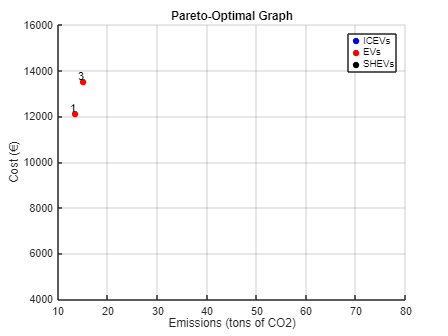

%     fitness_data(i) = powertrains(i).layout.layout_fitness;
% end
% T = table(MAE_data(:), emissions_data(:), cost_data(:), E_specific_data(:), fitness_data(:), 'VariableNames', {'MAE', 'Emissions (CO2 tons)', 'Cost (EUR)', 'E_specific', 'Fitness'});
% disp(T);
% 
% %% Pareto-Optimal Graph
% figure;
% hold on;
% scatter(emissions_data(icev == 1), cost_data(icev == 1), 'filled', 'MarkerFaceColor', 'b'); 
% scatter(emissions_data(ev == 1), cost_data(ev == 1), 'filled', 'MarkerFaceColor', 'r'); 
% scatter(emissions_data(shev == 1), cost_data(shev == 1), 'filled', 'MarkerFaceColor', 'k'); 
% 
% % Label the plotted points
% for i = 1:required_powertrains
%     text(emissions_data(i), cost_data(i), num2str(i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
% end
% 
% % Create labels
% ax = gca;
% ax.YAxis.Exponent = 0;
% xlabel('Emissions (tons of CO2)');
% ylabel('Cost (€)');
% ylim([4000 16000])
% xlim([10 80])

% title('Pareto-Optimal Graph');
% legend('ICEVs', 'EVs', 'SHEVs', 'location', 'Northeast');
% grid on;
% hold off;

The elapsed time is 21.55 minutes.


% 

The number of created powertrains is 6.


% %% Other information
% elapsed_time_minutes = elapsed_time / 60;
% fprintf('The elapsed time is %.2f minutes.\n', elapsed_time_minutes);
% fprintf('The number of created powertrains is %d.\n', created_powertrains);

%for i = 1:required_powertrains

figurine =   handle to deleted Figure


Error using figure
Argument must be a Figure object or a positive integer.

%figurine = powertrains(i).results.fig
%figure(figurine)
%end 

% Convert struct array to a cell array for compatibility
powertrains_cell = arrayfun(@(x) struct(x), powertrains, 'UniformOutput', false);
assignin('base', 'powertrains_cell', powertrains_cell);